# PyDES - A Performance Modeling Showcase

Giacomo Marciani

Department of Civil and Computer Engineering

University of Rome Tor Vergata

[gmarciani@acm.org](mailto:gmarciani@acm.org)

## `Abstract`

`This script visualizes the performance evaluation of the system proposed in [1]. The dataset is generated by the experiements implememted in [2].`

`This script allows to conduct the following studies:`

- `randomness``: the custom pseudo-random number generator is evaliuated in comparison with a past e present de-facto standard;`

- `transient analysis``: the transient period of the proposed system is evaluated taking into account the convergence of response time, throughput and mean population;`

- `performance evaluation``: the performance metrics of the proposed system are evaluated. In particular we assess response time, throughput, mean population, switched ratio and switched response time both classed/global and system/subsystems.`

`This work is inteded as a final test for the course in Performance Modeling of Computer Systems and Networks[7,8,9].`

## `Pseudo-Random Number Generation`

`Let us evaluate the pseudo-random number generator, defined by the following parameters, assessing its randomness with the Spectral Test[?], the Test of Extremes[?] and the Kolmogorov-Smirnov Analysis[?].`

modulus = 2147483647;
multipliers = [50812, 48271, 16807];

`Spectral Test`

`Let us see the results obtained with the Spectral Test.`

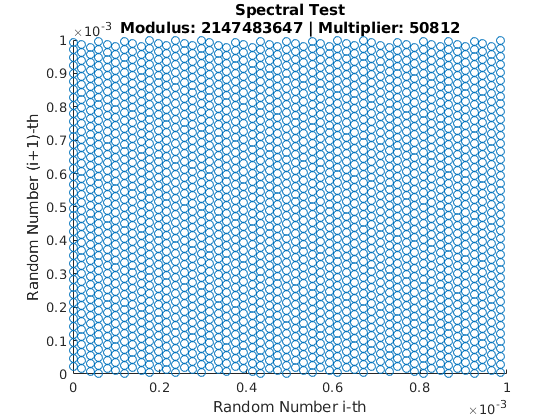

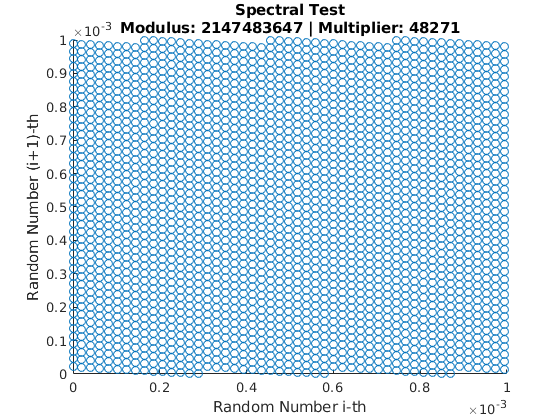

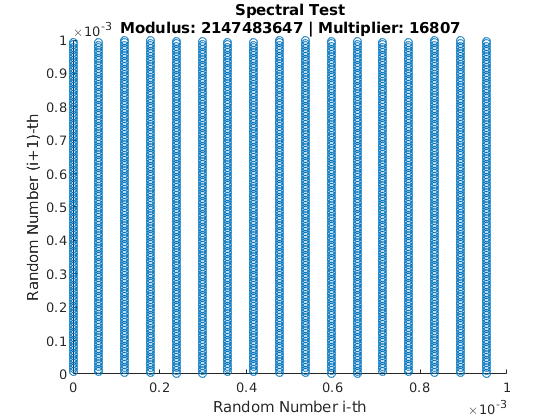

for multiplier = multipliers
    data = readtable(sprintf("random/out/spectral/mod%d_mul%d.csv", modulus, multiplier));
    
    x = data.u1;
    y = data.u2;
    
    scatter(x, y);
    title({"Spectral Test";sprintf("Modulus: %d | Multiplier: %d", modulus, multiplier)});
    xlabel("Random Number i-th");
    ylabel("Random Number (i+1)-th");
    figure;
end

`Test of Extremes`

`Let us see the results obtained with the Test of Extremes.`

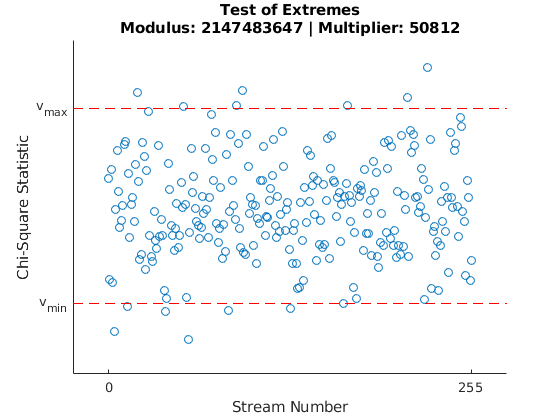

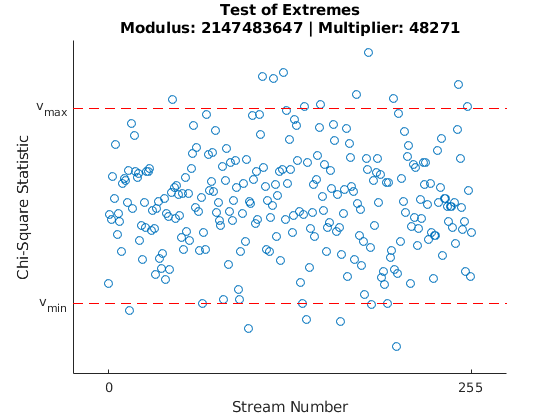

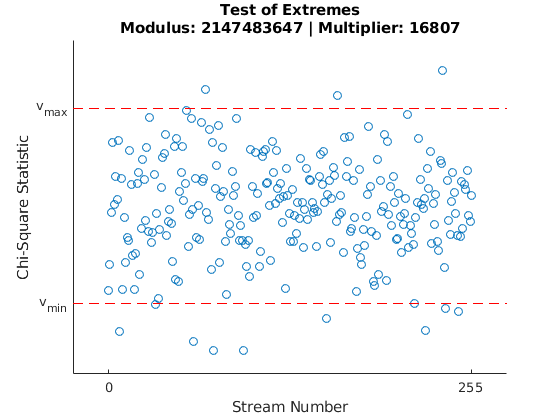

for multiplier = multipliers
    data = readtable(sprintf('random/out/extremes/mod%d_mul%d.csv', modulus, multiplier));
    report = readtable(sprintf('random/out/extremes/mod%d_mul%d_report.csv', modulus, multiplier));
    
    x = data.stream;
    y = data.value;
    
    criticalLower = report.critical_bounds_lower_bound;
    criticalUpper = report.critical_bounds_upper_bound;
    
    streams = length(x);
    offset = 25;
    
    scatter(x, y);
    hold on
    plot([-offset streams-1+offset], [1 1] * criticalLower, '--r')
    plot([-offset streams-1+offset], [1 1] * criticalUpper, '--r')
    hold off
    title({'Test of Extremes';sprintf('Modulus: %d | Multiplier: %d', modulus, multiplier)});
    xlabel('Stream Number');
    ylabel('Chi-Square Statistic');
    xlim([ -offset streams-1+offset ])
    set(gca,'xtick',[0 streams-1]);
    set(gca,'ytick',[criticalLower criticalUpper]);
    yticklabels({'v_{min}', 'v_{max}'});
    figure;
end

`Kolmogorov-Smirnov Analysis`

`Let us see the results obtained with the Kolmogorov-Smirnov Analysis.`

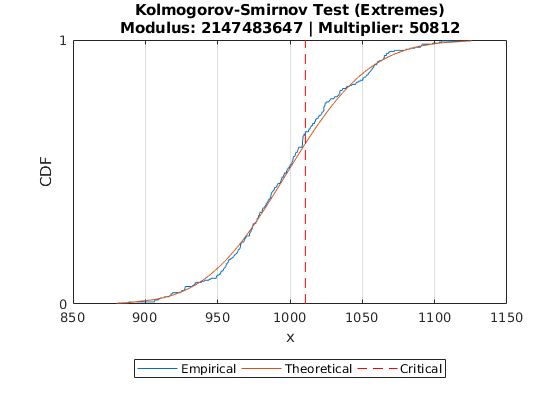

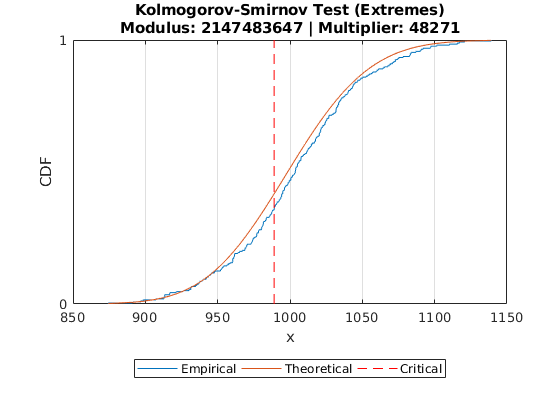

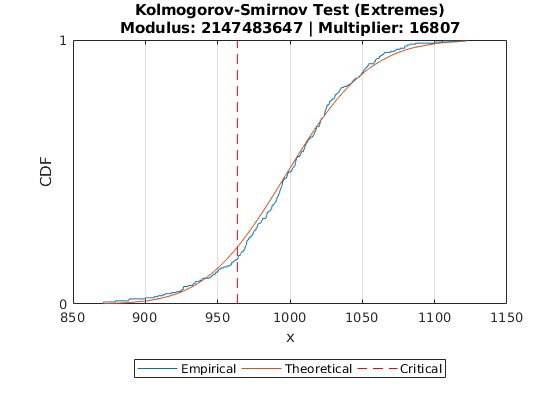

for multiplier = multipliers
    data = readtable(sprintf('random/out/kolmogorov-smirnov/extremes/mod%d_mul%d.csv', modulus, multiplier));
    report = readtable(sprintf('random/out/kolmogorov-smirnov/extremes/mod%d_mul%d_report.csv', modulus, multiplier));
    
    bins = report.test_parameters_bins;
    critical = report.ks_ks_point_x;
    
    empirical = sort(data.value);
    theoretical = chi2cdf(empirical, bins - 1);
    
    cdfplot(empirical)
    hold on
    plot(empirical, theoretical)
    plot([1 1] * critical, [0.0 1.0], '--r')
    hold off
    title({'Kolmogorov-Smirnov Test (Extremes)';sprintf('Modulus: %d | Multiplier: %d', modulus, multiplier)});
    xlabel('x');
    ylabel('CDF');
    set(gca,'ytick',[0.0 1.0]);
    legend('Empirical', 'Theoretical', 'Critical', 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end

## `Transient Analysis`

`Let us now study the transient period of the simulated system.`

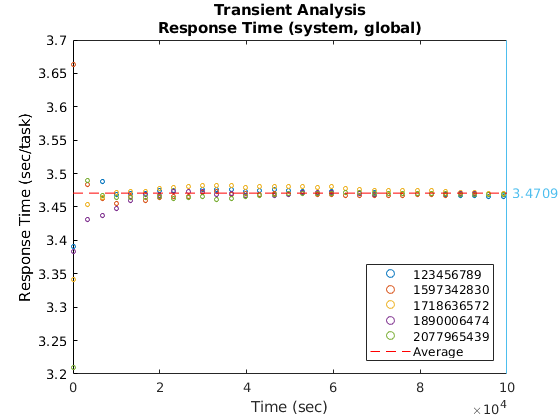

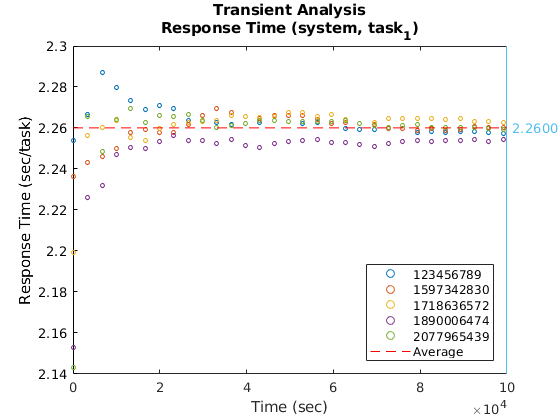

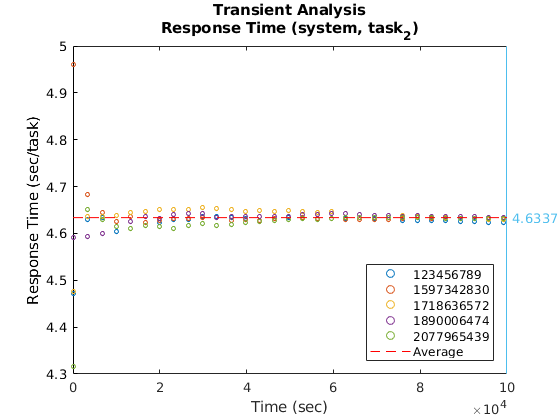

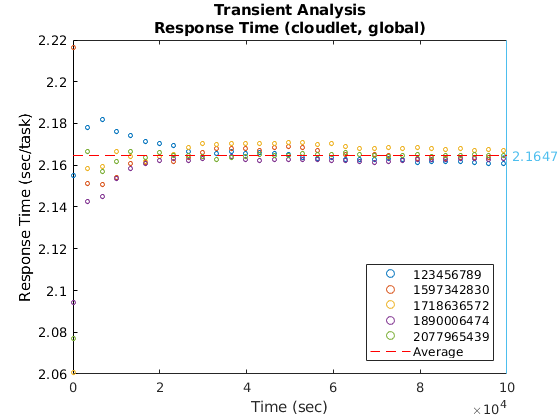

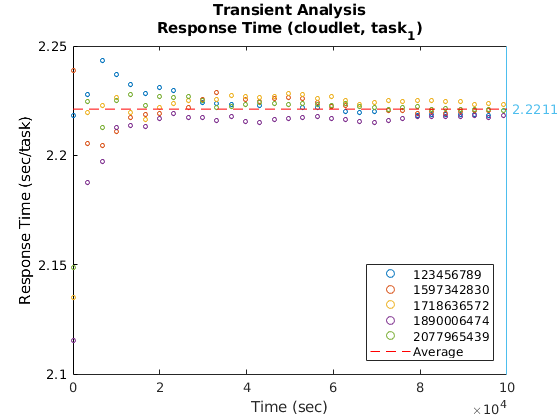

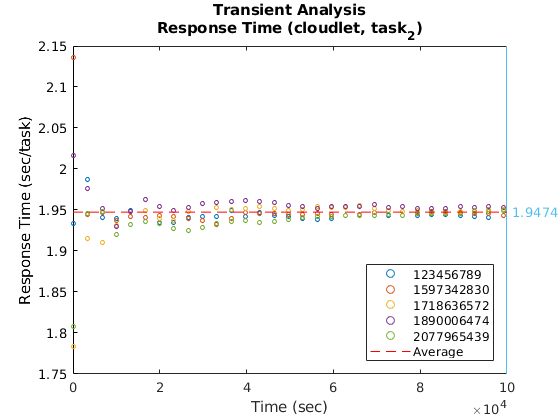

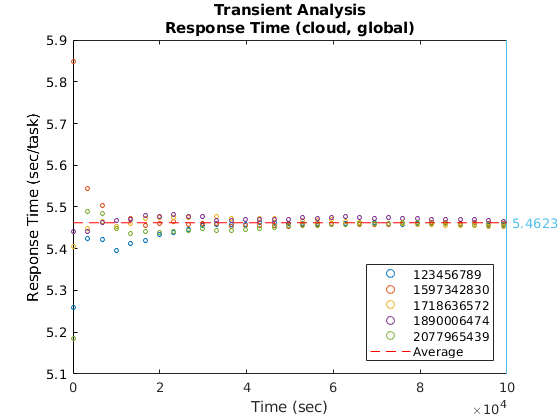

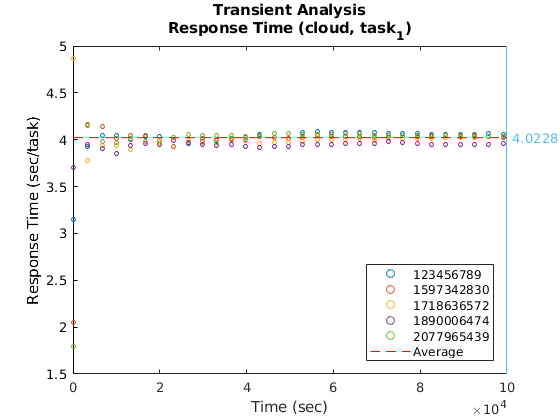

metrics   = ["response", "throughput", "population", "switched_ratio", "switched_response"];
sysScopes = ["system", "cloudlet", "cloud"];
tskScopes = ["global", "task_1", "task_2"];
units     = ["sec/task", "task/sec", "task", "ratio", "sec/task"];
headings  = ["Response Time", "Throughput", "Mean Population", "Switched Ratio", "Switched Response Time"];

samplePoints = 30;
ratioForMean = 0.5;

ls = dir('simulation/out/transient_analysis/seed_*');
seeds = strrep(string({ls.name}.'),'seed_','');

for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        for t = 1:length(tskScopes)
            metric = metrics(m);
            sys    = sysScopes(s);
            tsk    = tskScopes(t);
            unit   = units(m);
            
            heading = sprintf("%s (%s, %s)", headings(m), sys, tsk);
            entry   = sprintf("%s_%s_%s", metric, sys, tsk);    
            
            valuesForMean = [];
            
            title({'Transient Analysis', heading});
            xlabel('Time (sec)');
            ylabel(sprintf('%s (%s)', headings(m), unit));
            
            hold on
            
            for sd = 1:length(seeds)
                seed = seeds{sd,1};
                data = readtable(sprintf('simulation/out/transient_analysis/seed_%s/result.sampling.csv', seed));
                time = data.time;
                values = data.(char(entry));
                
                nValues = length(time);
                valuesForMean = cat(1, valuesForMean, values(floor(ratioForMean*nValues):1:end));        
                samplePace = floor(nValues/samplePoints);
            
                scatter(time(1:samplePace:end), values(1:samplePace:end), 10, 'LineWidth', 0.1, 'DisplayName', seed);    
            end
            
            hold off
            
            xl = xlim;
            yl = ylim;            
            
            avg = mean(valuesForMean);
            
            yyaxis right
            plot(xl, [avg avg], '--r', 'DisplayName', 'Average');
            ylim(yl);
            set(gca,'ytick', (avg));
            legend('show', 'Location', 'southeast', 'Orientation', 'vertical');
            figure;
        end
    end    
end

## `Performance Evaluation`

`Let us now visualize how performance metrics behave in response to threhsold variations.`

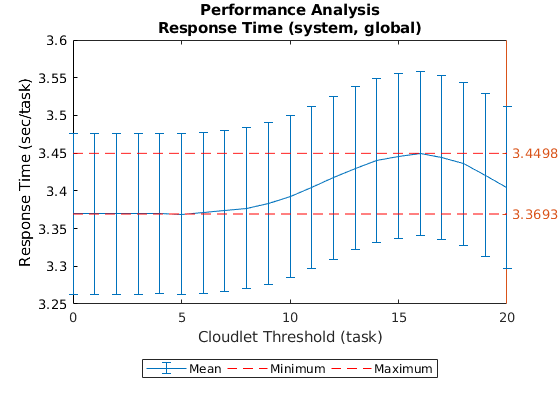

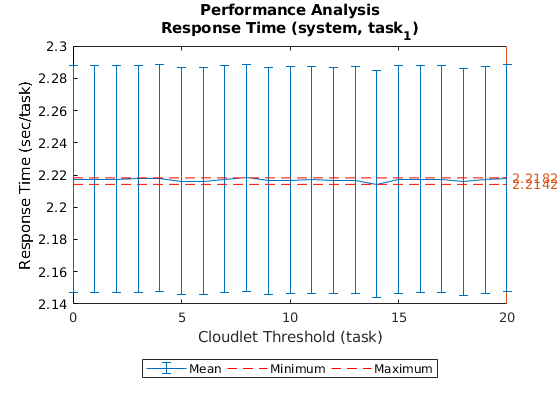

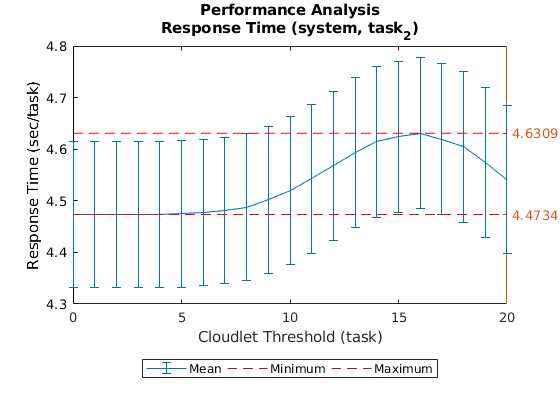

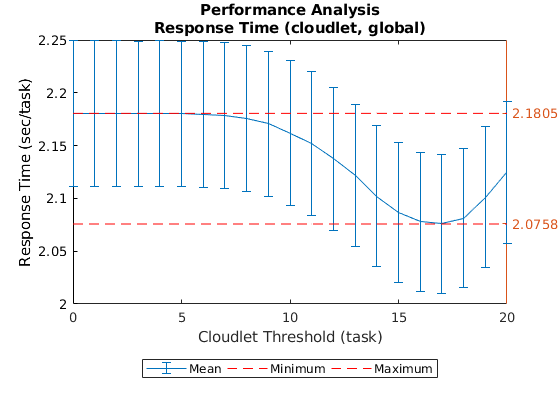

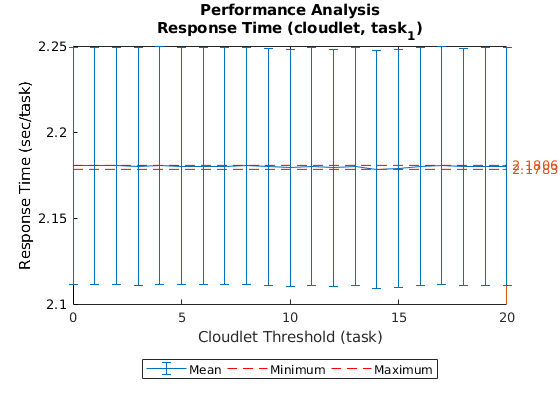

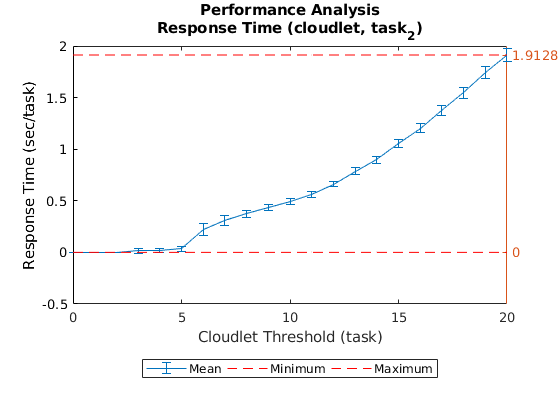

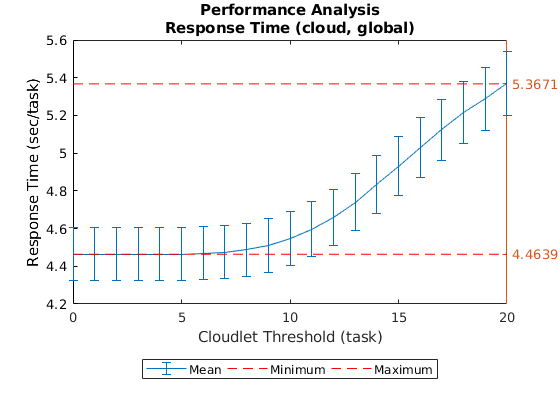

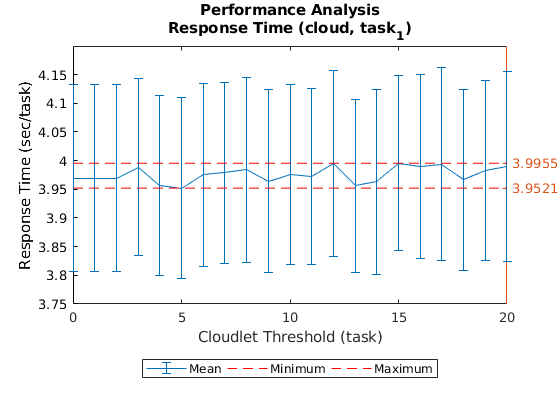

metrics   = ["response", "throughput", "population", "switched_ratio", "switched_response"];
sysScopes = ["system", "cloudlet", "cloud"];
tskScopes = ["global", "task_1", "task_2"];
units     = ["sec/task", "task/sec", "task", "ratio", "sec/task"];
headings  = ["Response Time", "Throughput", "Mean Population", "Switched Ratio", "Switched Response Time"];

data = readtable('simulation/out/performance_analysis/result.csv');

thresholds = data.system_cloudlet_threshold;

one = ones(size(thresholds));
for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        for t = 1:length(tskScopes)
            metric = metrics(m);
            sys = sysScopes(s);
            tsk = tskScopes(t);
            unit    = units(m);
            
            heading = sprintf("%s (%s, %s)", headings(m), sys, tsk);
            ventry  = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
            eentry  = sprintf("statistics_%s_%s_%s_cint", metric, sys, tsk);            
            
            values = data.(char(ventry));
            errors = data.(char(eentry));
            
            mn = min(values);
            mx = max(values);
            
            errorbar(thresholds, values, errors, 'DisplayName', 'Mean');
            title({'Performance Analysis', heading});
            xlabel('Cloudlet Threshold (task)');
            ylabel(sprintf('%s (%s)', headings(m), unit));
            
            yl = ylim;
            
            yyaxis right
            hold on
            plot(thresholds, ones(size(thresholds)) * mn, '--r', 'DisplayName', 'Minimum');
            plot(thresholds, ones(size(thresholds)) * mx, '--r', 'DisplayName', 'Maximum');
            hold off
            ylim(yl);
            if mn ~= mx
                set(gca,'ytick', [mn, mx]);
            else
                set(gca,'ytick', (mn));
            end
            legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
            figure;
        end
    end
end

`Let us now summarize the resulting metrics in a tabular fashion.`

tabularFields  = repmat("", length(metrics)+1, 1);
tabularEntries = repmat("", length(metrics)+1, 1);

tabularFields(1) = "threshold";
tabularEntries(1) = "system_cloudlet_threshold";

tblIdx = 2;
for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        for t = 1:length(tskScopes)
            metric = metrics(m);
            sys = sysScopes(s);
            tsk = tskScopes(t);
            tabularFields(tblIdx)  = sprintf("%s_%s_%s", metric, sys, tsk);
            tabularEntries(tblIdx) = sprintf("statistics_%s_%s_%s_mean", metric, sys, tsk);
            tblIdx = tblIdx + 1;
        end
    end
end

tabular = data(:,cellstr(tabularEntries));
tabular.Properties.VariableNames = cellstr(tabularFields);
disp(tabular);

    threshold    response_system_global    response_system_task_1    response_system_task_2    response_cloudlet_global    response_cloudlet_task_1    response_cloudlet_task_2    response_cloud_global    response_cloud_task_1    response_cloud_task_2    throughput_system_global    throughput_system_task_1    throughput_system_task_2    throughput_cloudlet_global    throughput_cloudlet_task_1    throughput_cloudlet_task_2    throughput_cloud_global    throughput_cloud_task_1    throughput_cloud_task_2    population_system_global    population_system_task_1    population_system_task_2    population_cloudlet_globa

## `Distribution Analysis`

`Let us now study the probability distribution function and the cumulative distribution function of a given metric. Please, notice that the variable ``dists`` should be modified accordingly to the result reported by the Distribution Fitter.`

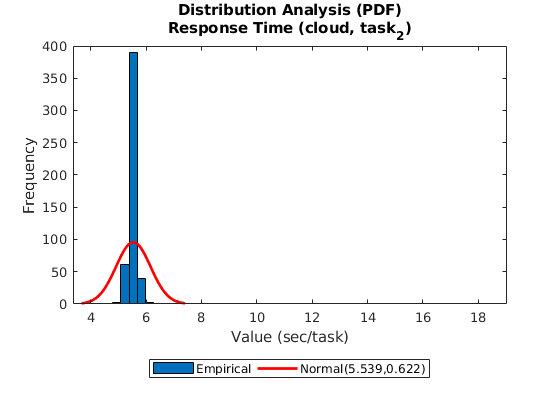

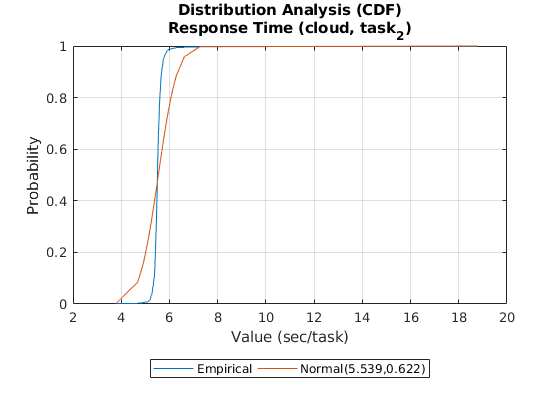

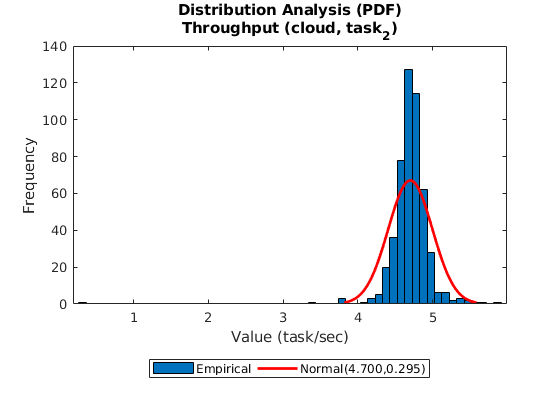

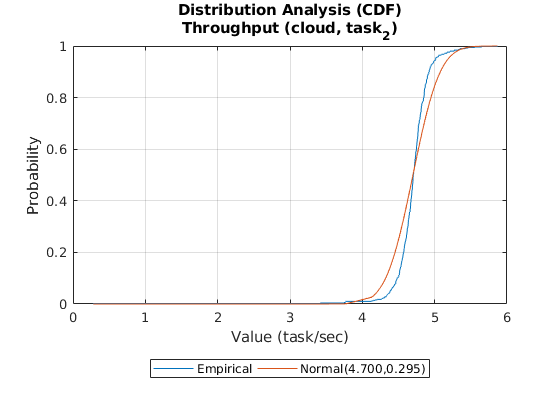

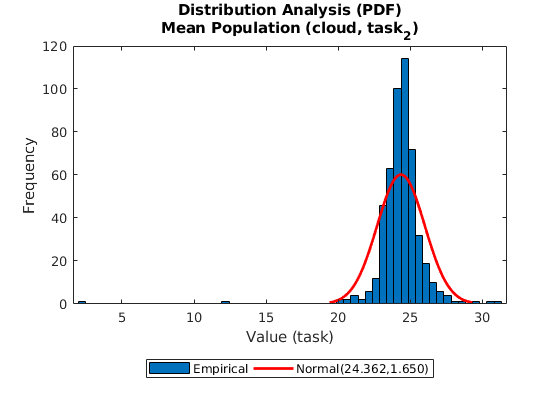

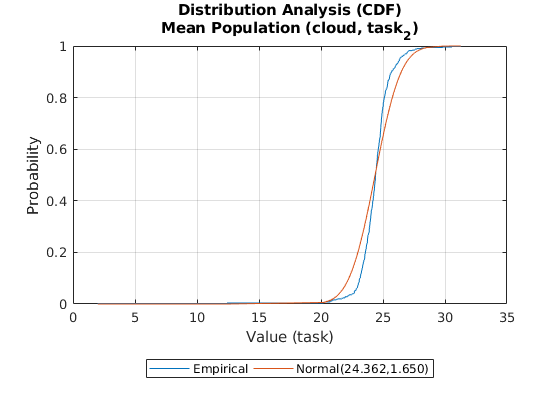

metrics   = ["response", "throughput", "population"];
sysScopes = ["system", "cloudlet", "cloud"];
tskScopes = ["global", "task_1", "task_2"];
units     = ["sec/task", "task/sec", "task"];
headings  = ["Response Time", "Throughput", "Mean Population"];
%dists    = ["GeneralizedExtremeValue", "GeneralizedExtremeValue", "GeneralizedExtremeValue"];
dists     = ["Normal", "Normal", "Normal"];

S = 20;

data = readtable(sprintf('simulation/out/performance_analysis/%d/result.sampling.csv', S));

for m = 1:length(metrics)
    for s = 1:length(sysScopes)
        for t = 1:length(tskScopes)
            metric = metrics(m);
            unit = units(m);
            dist = dists(m);
            
            heading = sprintf("%s (%s, %s)", headings(m), sys, tsk);
            entry = sprintf("%s_%s_%s", metric, sys, tsk);
            
            empirical = sort(data.(char(entry)));
            
            %%
            % PDF
            %%
            bins = size(histcounts(empirical), 2);
            dparams = fitdist(empirical, char(dist));
            histfit(empirical, bins, char(dist));
            title({'Distribution Analysis (PDF)', heading});
            xlabel(sprintf('Value (%s)', unit));
            ylabel('Frequency');
            %legend('Empirical', sprintf("%s(%.3f,%.3f,%.3f)", dist, dparams.k, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            legend('Empirical', sprintf("%s(%.3f,%.3f)", dist, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            figure;
            
            %%
            % CDF
            %%
            cdfplot(empirical);
            %cdfTheoretical = cdf(char(dist), empirical, dparams.k, dparams.sigma, dparams.mu);
            cdfTheoretical = cdf(char(dist), empirical, dparams.mu, dparams.sigma);
            hold on
            plot(empirical, cdfTheoretical);
            hold off
            
            title({'Distribution Analysis (CDF)', heading});
            xlabel(sprintf('Value (%s)', unit));
            ylabel('Probability');
            %legend('Empirical', sprintf("%s(%.3f,%.3f,%.3f)", dist, dparams.k, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            legend('Empirical', sprintf("%s(%.3f,%.3f)", dist, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
            figure;
        end
    end
end

## `Verification`

`Let us now verify the correctness of the experimental model by comparing the computed experimental results with the expected theoretical ones.`

`To this aim, we leverage the Markov Chain modeling of the system so to use the calculated steady-state probabilities to compare experimental performance indeces with the theoretical ones`

data = readtable('verification/out/markov_analysis/transition_matrix.csv');
stateNames = readtable('verification/out/markov_analysis/states.csv');

transitionMatrix = data{:,:};
[V,D] = eig(transitionMatrix');
P = V(:,1)';P = P./sum(P);
disp(array2table(P, 'VariableNames', table2cell(stateNames)));

       A0A0          A0A1          A0A2          A0A3          A0A4          A0A5          A0A6          A0A7          A0A8          A0A9         A0A10         A0A11         A0A12         A0A13         A0A14         A0A15         A0A16         A0A17         A0A18         A0A19        A0A20          A1A0          A1A1          A1A2          A1A3          A1A4          A1A5          A1A6          A1A7          A1A8          A1A9         A1A10    

## `References`

- `Relazione, `[`https://www.cryptocompare.com`](https://www.cryptocompare.com)

- `Repo Github, `[`https://www.github.com/gmarciani/pydes`](https://www.cryptocompare.com)

- `Performance Modeling of Computer Systems and Networks, `[`http://didattica.uniroma2.it/informazioni/index/insegnamento/172514-Performance-Modeling-Of-Computer-Systems-And-Networks`](http://didattica.uniroma2.it/informazioni/index/insegnamento/172514-Performance-Modeling-Of-Computer-Systems-And-Networks)

- `Leemis, Lawrence M., and Stephen Keith Park. ``Discrete-event simulation: A first course``. Upper Saddle River, NJ: Pearson Prentice Hall, 2006.`

- `Harchol-Balter, Mor. ``Performance modeling and design of computer systems: queueing theory in action``. Cambridge University Press, 2013.`